# Проект "Самобалансирующийся манипулятор"

Выполнили:

Артем Ларченков (369936) 

Денис Куровский (371255)

Холодилов Алексей (371924) 

clear all; clc;

m0 = 1.4;
m1 = 0.25;
m2 = 0.05;
m3 = 0.15;
m4 = 0.25;

TimeStop = 10; % с, время работы симуляции

Под роботом в данной работе поразумевается основание с установленным на нём манипулятором, полученным в результате выполенения 4 практической работы.

**********ДОБАВИТЬ КАРТИНКИ И ПЕРЕПИСАТЬ БРЕД СНИЗУ************

Цель: симуляция гипотетического робота, являющимся самобалансирующимся основанием, и установленным на нем манипулятором, который не был предварительно подготовлен для данных условий работы.

Задачи: 

1) Получение данных об отклонении от изначального положения и угла наклона корпуса основания;

2) Получение данных об развиваемых скоростях и ускорениях основания;

3) Получение данных об развиваемых силах и моментах во время работы робота (относительно основания);

4) Сравнение графиков требуемого и действительного положений манипулятора;

5) Понять пригодность совмещения самобалансирующегося основания и манипулятора без изменения конструкции.

#### Спецификация выбранного мотора 

Name                                                                                 ECX SPEED 19 L, BLDC motor

Nominal voltage, V                                                            18

No load speed, rpm                                                           60800

No load current, mA                                                           376

Nominal speed, rpm                                                           57200

Nominal torque (max. continuous torque), m*Nm              23.9

Nominal current (max. continuous current), A                    8.71

Stall torque, m*Nm                                                             503

Stall current, A                                                                    178

Max. efficiency, %                                                               91.2

Terminal resistance, Ω                                                        0.101

Terminal inductance, mH                                                    0.0096

Torque constant, m*Nm/A                                                   2.82

Speed constant, rpm/V                                                       3390

Speed/torque gradient, rpm/m*Nm                                     121

Mechanical time constant, ms                                             2.27

Rotor inertia, g*cm2                                                            1.79

Weight of motor, g                                                               108

Link:    https://www.maxongroup.com/medias/sys_master/root/8882181406750/EN-21-210.pdf

PRO
pid_sim = sim("PRO.slx");  

### Передвижение шасси

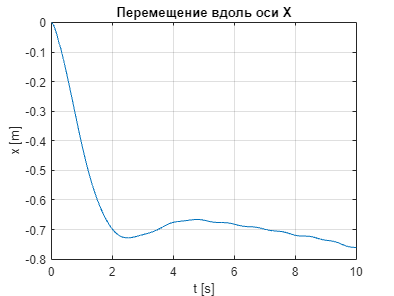

figure;
plot(pid_sim.ws.p_act.time, pid_sim.ws.p_act.data);
title('Перемещение вдоль оси Х');
grid on;
xlabel('t [s]');
ylabel('x [m]');

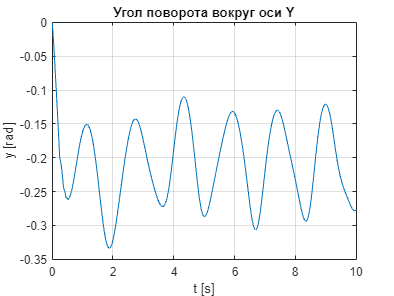

figure;
plot(pid_sim.q.time, pid_sim.q.signals.values(:,1));
title('Угол поворота вокруг оси Y');
grid on;
xlabel('t [s]');
ylabel('y [rad]');

### Скорости и ускорение шасси

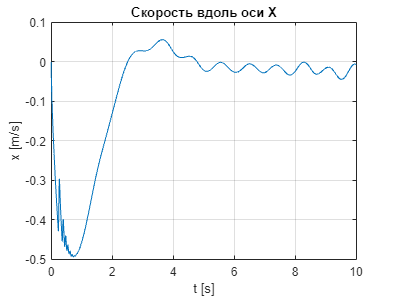

figure;
plot(pid_sim.ws.p_v.time, pid_sim.ws.p_v.data);
title('Скорость вдоль оси Х');
grid on;
xlabel('t [s]');
ylabel('x [m/s]');

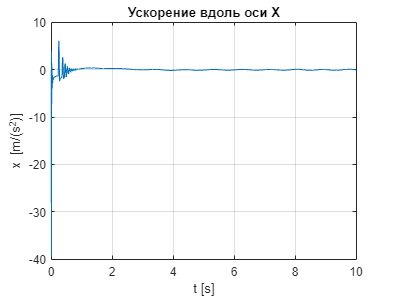

figure;
plot(pid_sim.ws.p_a.time, pid_sim.ws.p_a.data);
title('Ускорение вдоль оси Х');
grid on;
xlabel('t [s]');
ylabel('x [m/(s^2)]');

### Траектория манипулятора

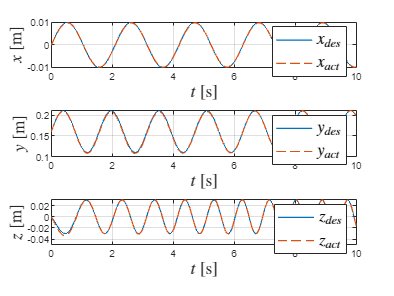

figure;
subplot(3,1,1);
title("PID positions")
plot(pid_sim.simout.p_des.time, pid_sim.simout.p_des.data(:,1),...
     pid_sim.simout.p_act.x.time, pid_sim.simout.p_act.x.data,'--', 'linewidth', 1);
grid on;
legend('$x_{des}$', '$x_{act}$',  'fontsize',14,'interpreter','latex');
ylabel('$x$ [m]', 'fontsize',14,'interpreter','latex');
xlabel('$t$ [s]', 'fontsize',14,'interpreter','latex');
subplot(3,1,2);
plot(pid_sim.simout.p_des.time, pid_sim.simout.p_des.data(:,2),...
     pid_sim.simout.p_act.y.time, pid_sim.simout.p_act.y.data,'--', 'linewidth', 1);
grid on;
legend('$y_{des}$', '$y_{act}$',  'fontsize',14,'interpreter','latex');
ylabel('$y$ [m]', 'fontsize',14,'interpreter','latex');
xlabel('$t$ [s]', 'fontsize',14,'interpreter','latex');
subplot(3,1,3);
plot(pid_sim.simout.p_des.time, pid_sim.simout.p_des.data(:,3),...
     pid_sim.simout.p_act.z.time, pid_sim.simout.p_act.z.data,'--', 'linewidth', 1);
grid on;
legend('$z_{des}$', '$z_{act}$',  'fontsize',14,'interpreter','latex');
ylabel('$z$ [m]', 'fontsize',14,'interpreter','latex');
xlabel('$t$ [s]', 'fontsize',14,'interpreter','latex');

### Траектория манипулятора

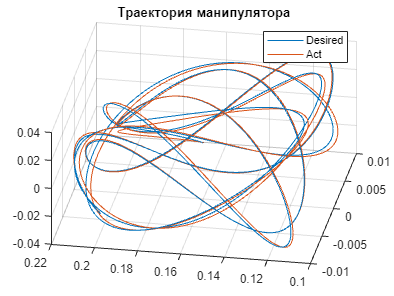

figure;
hold on;
grid on;
plot3(pid_sim.simout.p_des.Data(:,1),pid_sim.simout.p_des.Data(:,2),pid_sim.simout.p_des.Data(:,3));
plot3(pid_sim.simout.p_act.x.Data,pid_sim.simout.p_act.y.Data,pid_sim.simout.p_act.z.Data);
legend("Desired","Act");
title("Траектория манипулятора")
hold off;
view([-80 45])

## Заключение

По итоге полученных данных с данной модели возможно сделать следующий вывод: из-за постоянной смены центра масс сделать самобансирующийся манипулятор без изменения конструкции не имеет смысл из-за сильного влияния наклона основания на траекторию манипулятора.  